% Define el nombre del archivo G-code
nombreArchivo = 'barrido_altavoz.gcode'; %Introducir el nombre de la trayectora que se quiera ejecutar

% Configuración del puerto serie
port = 'COM8';  %Introducir puerto correspondiente a donde se conecta el equipo
baudrate = 115200;  % Velocidad de transmisión en baudios
ser = serialport(port, baudrate);
fopen(ser);

recorder1 = audiorecorder(44100,16,1,1);

%Lectura del fichero de instrucciones

instrucciones = char(lectura(nombreArchivo))

% Envio de la trayectoria, captura de la grabación y datos de la posición

[salida] = trayectoria_grabacion2(ser,instrucciones,recorder1);

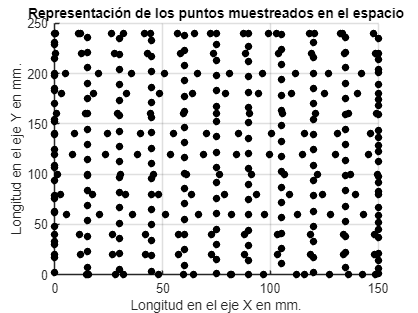

%Representación de la trayectoria 

scatter(salida(:,1),salida(:,2),'k','filled')
grid on
xlabel("Longitud en el eje X en mm.")
ylabel("Longitud en el eje Y en mm.")
title("Representación de los puntos muestreados en el espacio")

%Cálculo de la distancia entre los puntos capturados

for z=1:length(salida)-1
    distancia_puntos(z)=sqrt((abs(salida(1+z,1))-abs(salida(z,1)))^2+((abs(salida(1+z,2))-abs(salida(z,2)))^2));
end

%Cargar archivo grabado y procesado

[signal, Fs] = audioread("altavoz_4000hz.wav");
[samples, channels] = size(signal);
time = linspace(0,samples/Fs,samples);
signal = abs(signal);
muestras_original = 1:samples;

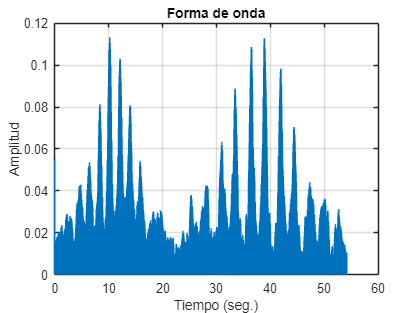

%Forma de onda de la señal grabada

plot(time,signal)
grid on 
title ("Forma de onda")
xlabel("Tiempo (seg.)")
ylabel("Amplitud")

pref = 10^-12;

% Calcular la potencia de la señal en unidades lineales
potencia_lineal = signal.^2;

muestra_anterior = 0;
fin_anterior = 0;

A_db = zeros(1,length(distancia_puntos));
for m = 1:length(distancia_puntos)   

    vel_media = ((salida(m,3)+salida(m+1,3))/(2)); % Cálculo de la velocidad media

    if vel_media == 0

        tiempo_trayectoria = 0;
    else
        tiempo_trayectoria = (distancia_puntos(m))/(((salida(m,3)+salida(m+1,3))/(2))/60); % multiplicamos por 60 para pasar la velocidad de mm/min a mm/seg
    end

    ventana =  floor(Fs*tiempo_trayectoria); % Tamaño de la ventana
    inicio = fin_anterior + 1; % Muestra de inicio de la ventana
    fin = ventana + fin_anterior; % Muestra de final de la ventana

    muestras = signal(inicio:fin);
    media_amplitud = (rms(muestras)); % Media rms de la ventana

    muestra_anterior = ventana;
    fin_anterior = fin;

    A_lineal(m) = media_amplitud;

end

pot_lineal = A_lineal.^2;
A_db = 10*log10(pot_lineal./pref);

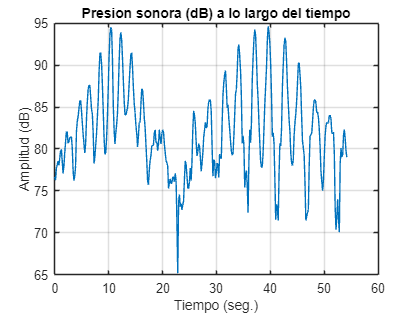

% Representación de los dB a lo largo del tiempo

t = linspace(0,samples/Fs,length(A_db));

figure
plot(t,A_db-2.5)
grid on 
title("Presion sonora (dB) a lo largo del tiempo")
grid on
xlabel("Tiempo (seg.)")
ylabel("Amplitud (dB)")

%Cálculo del tamaño de la matriz de datos

max_pos = max(salida, [], 1);
matriz_size_x = floor(max_pos(1) / max(distancia_puntos)) ; 
matriz_size_y = floor(max_pos(2) / max(distancia_puntos)) ; 

%Declaración de ejes para las representaciones espaciales

eje_x = linspace(0,max_pos(1),length(A_db));
eje_y = linspace(0,max_pos(2),length(A_db));

%Creación del mallado 

[Xq, Yq] = meshgrid(eje_x, eje_y); 

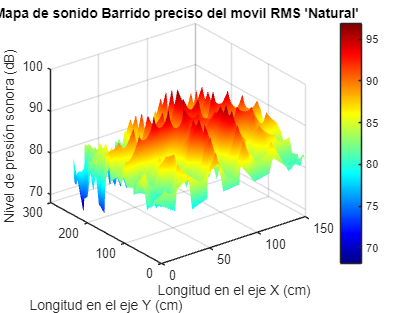

% Interpolar los datos (Interpolación natural) con el mallado
Zq = griddata(salida(1:end-1,1), salida(1:end-1,2), A_db, Xq, Yq,'natural');

figure
S = surf(Xq,Yq,Zq);

title("Mapa de sonido Barrido preciso del movil RMS 'Natural' ")
xlabel("Longitud en el eje X (cm)")
ylabel("Longitud en el eje Y (cm)")
zlabel("Nivel de presión sonora (dB)")
colorbar
shading interp
colormap(jet)

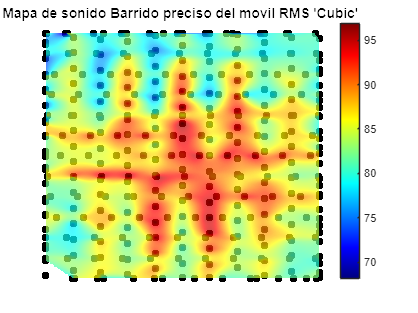

%Superposición de los datos con los puntos muestreados

figure

S = surf(Xq,Yq,Zq);

title("Mapa de sonido Barrido preciso del movil RMS 'Cubic' ")
xlabel("Longitud en el eje X (cm)")
ylabel("Longitud en el eje Y (cm)")
zlabel("Nivel de presión sonora (dB)")
colorbar
shading interp
colormap(jet)
S.FaceAlpha = 0.7;
view([0 90])
axis('off')

hold on
scatter(salida(:,1),salida(:,2),'k','filled')
hold off

% Ejemplo de superposición de imagen con el mapa.

referencia = imread('altavoz.jpg');
referencia=imrotate(referencia,180);


%Puntos de referencia, cambiarán en función dela imagen
p_00=[541 974];
p_20_0 = [1074 991];
p_0_20 = [501 94];

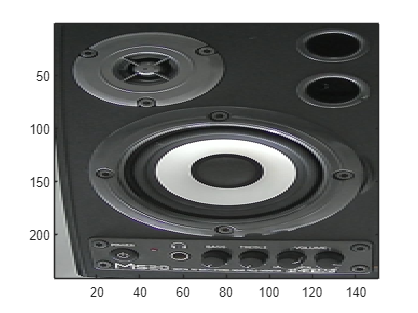

%Ajuste de la imagen al tamaño de los datos

figure

referencia_recortada = imcrop(referencia,[p_0_20(1) p_0_20(2) p_00(1) p_20_0(2)-100]);
referencia_recortada = (referencia_recortada);
referencia_recortada = imresize(referencia_recortada,[max(Yq,[],"all") max(Xq,[],"all")]);

image(referencia_recortada)

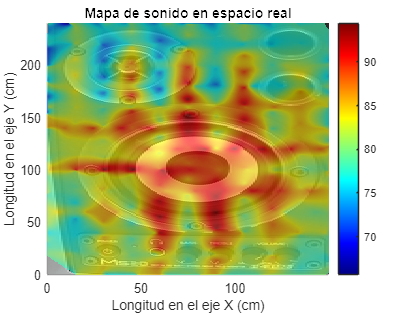

%Superposición del mapa con la imagen real

Zq = griddata(salida(1:end-1,1), salida(1:end-1,2), (A_db-2.5), Xq, Yq,'natural');

figure
S = surf(Xq,Yq,Zq);

title("Mapa de sonido en espacio real")
xlabel("Longitud en el eje X (cm)")
ylabel("Longitud en el eje Y (cm)")
zlabel("Nivel de presión sonora (dB)")
colorbar
shading interp
colormap(jet)
S.FaceAlpha = 0.6;
grid on
view([0 90])

xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(referencia_recortada)

hold off

% Otro ejemplo con otra imagen

altavoz2 = imread('altavoz2.jpg');

altavoz_recortado = imresize(altavoz2,[max(Yq,[],"all") max(Xq,[],"all")]);

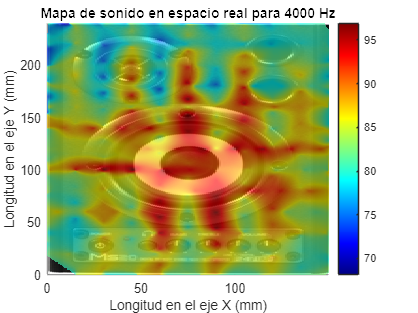

% Superposición del mapa de presión con la imagen

Zq = griddata(salida(1:end-1,1), salida(1:end-1,2), (A_db), Xq, Yq,'natural');

figure
S = surf(Xq,Yq,Zq);

title("Mapa de sonido en espacio real para 4000 Hz")
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")
zlabel("Nivel de presión sonora (dB)")
colorbar
shading interp
colormap(jet)
S.FaceAlpha = 0.6;
grid on
view([0 90])

xlim([0 max_pos(1)])
ylim([0 max_pos(2)])
hold on

image(flip(altavoz_recortado))

hold off

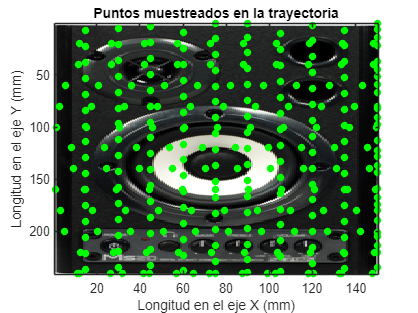

% Representación de la imagen con los puntos muestreados

figure

image(altavoz_recortado)
title("Puntos muestreados en la trayectoria")
xlabel("Longitud en el eje X (mm)")
ylabel("Longitud en el eje Y (mm)")

hold on

scatter(salida(:,1),salida(:,2),'g','filled')

hold off